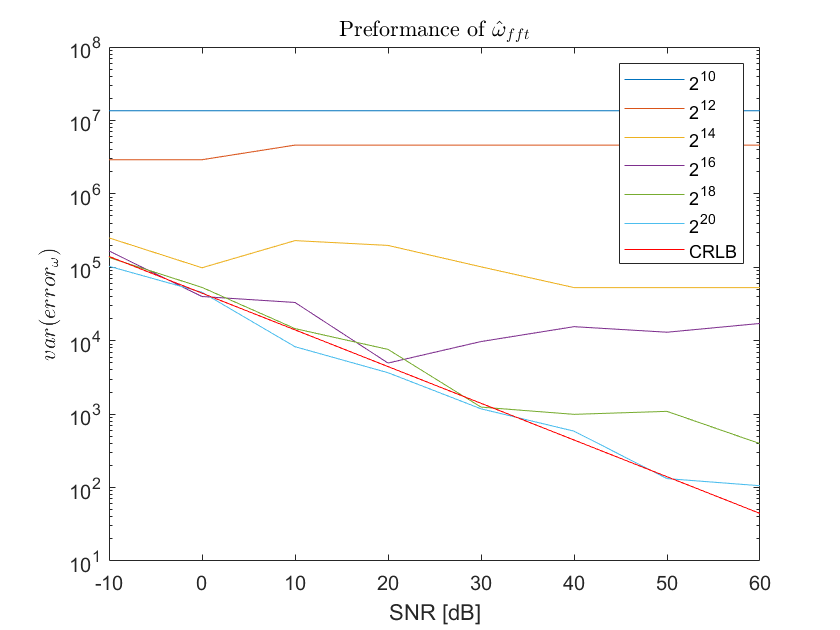

clear all;
clear figure;

%Constants
N = 513;
n_0 = -256;
T = 10.^(-6);
f_0 = 10.^5;
F_s = 10^6;
w_0 = 2.*pi.*f_0;
A = 1;
k = 10:2:20;
phi = pi./8;
n = n_0:n_0+N-1;
P = (N.*(N-1))./(2);
Q = (N.*(N-1).*(2.*N-1))./(6);

%Making a vector of sigma based on snr
snr = -10:10:60;

sigma = zeros(1,8);


%The signal of x
signal = A.*exp(1i.*(w_0.*n.*T+phi));

steps = 200;

%Vectors 
w_fft = zeros(1, steps);
phi_fft = zeros(1, steps);
var_error_w = zeros(1, 8);
var_error_phi = zeros(1, 8);
phi_error = zeros(1, steps);
w_error = zeros(1, steps);
CRLB_w = zeros(1, 8);
CRLB_phi = zeros(1,8);
w_mle = zeros(1, steps);
phi_mle = zeros(1, steps);
var_w_min = zeros(1,8);
var_phi_min = zeros(1,8);


for j=1:6
   %Number of bins
   M = 2.^k(j);
   
    for j_1=1:8
        
           %Calculating noise based on SNR
           sigma(j_1)= sqrt(A.^2./(db2mag(snr(j_1)).*2));
           noise = normrnd(0, sigma(j_1), steps, N) + 1i.*normrnd(0, sigma(j_1), steps, N);
           
           for j_2=1:steps
               %Calculating the fft based estimators
                x = signal + noise(j_2,:);
    
                x_fft = fft(x,M);
    
                [argvalue, argmax] = max(abs(x_fft));
                m = argmax;
                
    
                w_fft(j_2) = (2.*pi.*m)./(M.*T);
                w_error(j_2) =(w_0 - w_fft(j_2)).^2;
                

                phi_fft(j_2) = angle(exp(-1i*w_fft(j_2)*n_0*T).*(x_fft(m)));
                phi_error(j_2) = (phi - phi_fft(j_2)).^2;
                
                % Numerical search method
                 if k(j) == 10
                     
                    func1 = @(w) sum(abs(x - (A*exp(1i*(w*n*T + phi)))));

                    [vals1, ~, exitflag1, output1] = fminsearch(@(input) func1(input(1)), mean(w_fft));

                    w_mle(j_2) = vals1(1);
                    
                    
                    
                    func2 = @(p) sum(abs(x - (A*exp(1i*(w_0*n*T + p)))));

                    [vals2, ~, exitflag2, output2] = fminsearch(@(input) func2(input(1)), mean(phi_fft));

                    phi_mle(j_2) = vals2(1);
                    
                 end 
    
           end 
           
           %Calculations for the variances 
           var_error_w(j_1) =(1/steps)*(sum(w_error));
           var_error_phi(j_1) = (1/steps)*(sum(phi_error));
           
           var_w_min(j_1) = var(w_0 - w_mle);
           var_phi_min(j_1) = var(phi - phi_mle);
           
           %{
            if k(j) == 10
                fprintf('Estimated w: %.0f (%.3f%% off)\n', mean(w_mle), 100*(mean(w_mle) - w_0)/w_0);
                fprintf('Estimated phi: %f (%.3f%% off)\n', mean(phi_mle),100*(mean(phi_mle) - phi)/phi);
                fprintf('SNR: %f \n', snr(j_1)); 
            end 
           %}
    end
    
    %Plotting fft based estimators for each number of bins
    figure(1); 
    semilogy((snr), var_error_w ); hold on;
    grid
    
    
    figure(2);
    semilogy((snr), var_error_phi ); hold on; 
    grid
  
    %Plotting numerical search estimators
    if k(j)== 10
        figure(3)
        semilogy((snr), var_w_min); hold on;
        grid;
    
        figure(4)
        semilogy((snr), var_phi_min); hold on;
        grid;   
    end
     
end

 


for i_1 = 1:8
    %Calculations for CRLB
    CRLB_w(i_1) = (12.*(sigma(i_1)).^2)/(A.^2.*T.^2.*N.*(N.^2-1));
    CRLB_phi(i_1) = ((12.*(sigma(i_1)).^2).*(n_0.^2.*N+2.*n_0.*P+Q))./(A.^2.*N.^2.*(N.^2-1));
    
   %Adding the CRLB to all plots
    figure(1); 
    semilogy((snr), CRLB_w, 'r' ); hold on;
    grid
    
    figure(2); 
    semilogy((snr), CRLB_phi, 'r' ); hold on;
    grid
    
  
    figure(3)
    semilogy((snr), CRLB_w); hold on;
    grid;
    
    figure(4)
    semilogy((snr), CRLB_phi); hold on;
    grid;
    
end

%Final plots
figure(1)
title('Preformance of $$\hat{\omega}_{fft}$$', 'Interpreter',"latex"); 
xlabel('SNR [dB]');  
ylabel('$$var(error_{\omega})$$', 'Interpreter',"latex"); 
legend( '2^{10}', '2^{12}', '2^{14}', '2^{16}', '2^{18}', '2^{20}', 'CRLB');

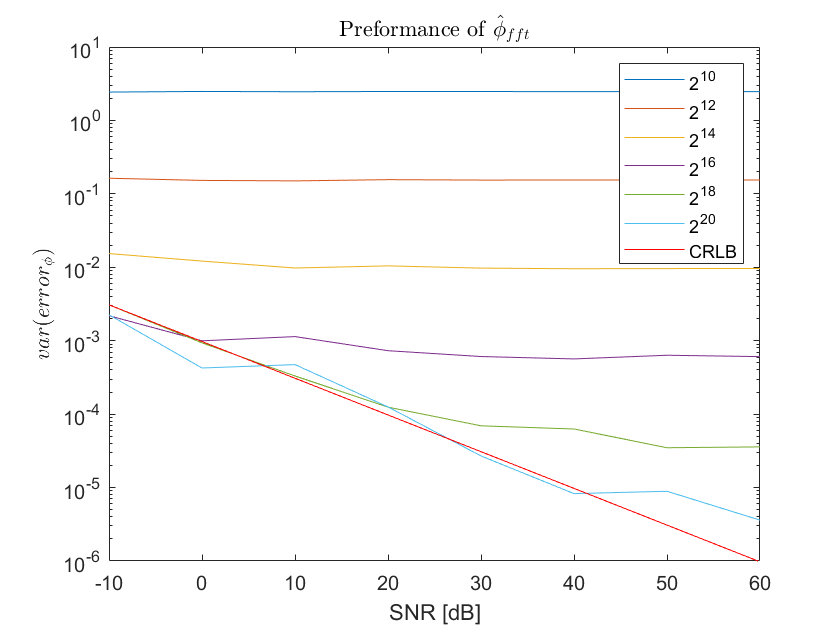



figure(2)
title('Preformance of $$\hat{\phi}_{fft}$$', 'Interpreter',"latex")
xlabel('SNR [dB]') 
ylabel('$$var(error_{\phi})$$', 'Interpreter',"latex")
ylim([10e-07 10])
legend('2^{10}', '2^{12}', '2^{14}', '2^{16}', '2^{18}', '2^{20}', 'CRLB');

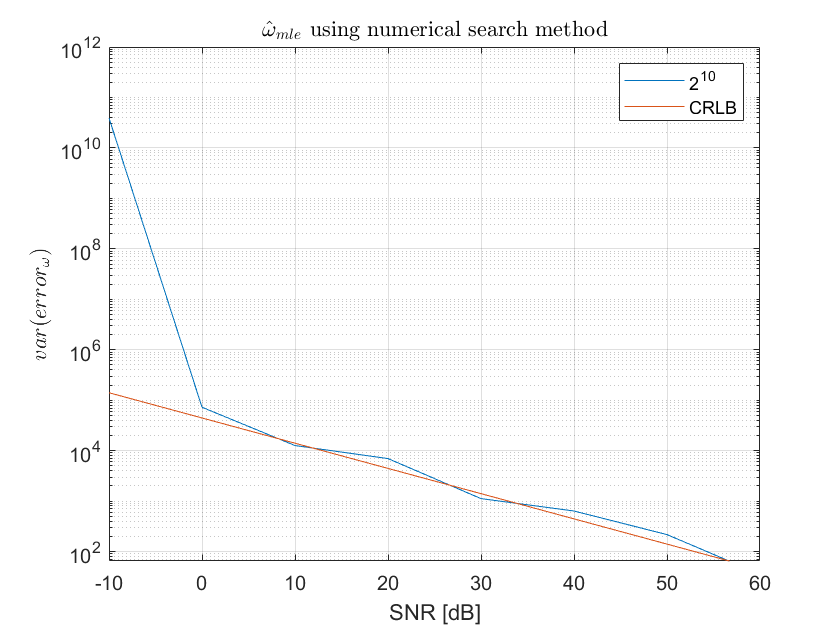




figure(3)
title('$$\hat{\omega}_{mle}$$ using numerical search method', 'Interpreter',"latex");
ylim([65 10^12]);
xlabel('SNR [dB]') 
ylabel('$$var(error_{\omega})$$', 'Interpreter',"latex") 
legend( '2^{10}', 'CRLB');

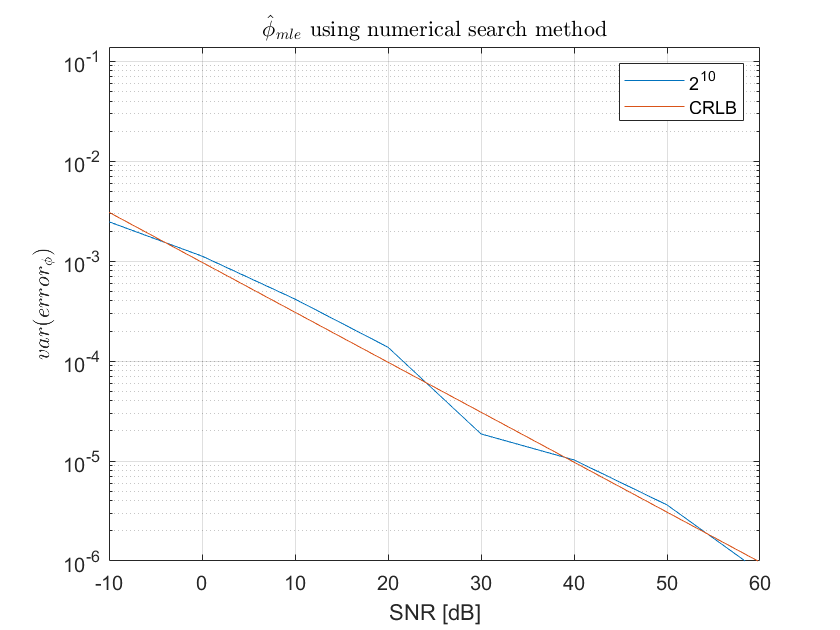


figure(4)
title('$$\hat{\phi}_{mle}$$ using numerical search method', 'Interpreter',"latex")
ylim([1e-06 0.139])
xlabel('SNR [dB]') 
ylabel('$$var(error_{\phi})$$', 'Interpreter',"latex"') 
legend( '2^{10}', 'CRLB');